# Modelado, análisis, simulación y control de un fenómeno vibratorio

Adrián Augusto Ferrer Orgaz A01749394

Carlos de Jesús Ávila González A01750220

Elisa María Bonilla Martín A01028576

Enrique Maldonado Chavarría A01652370

Edificio de n pisos sujeto a movimiento excitación sísmica.

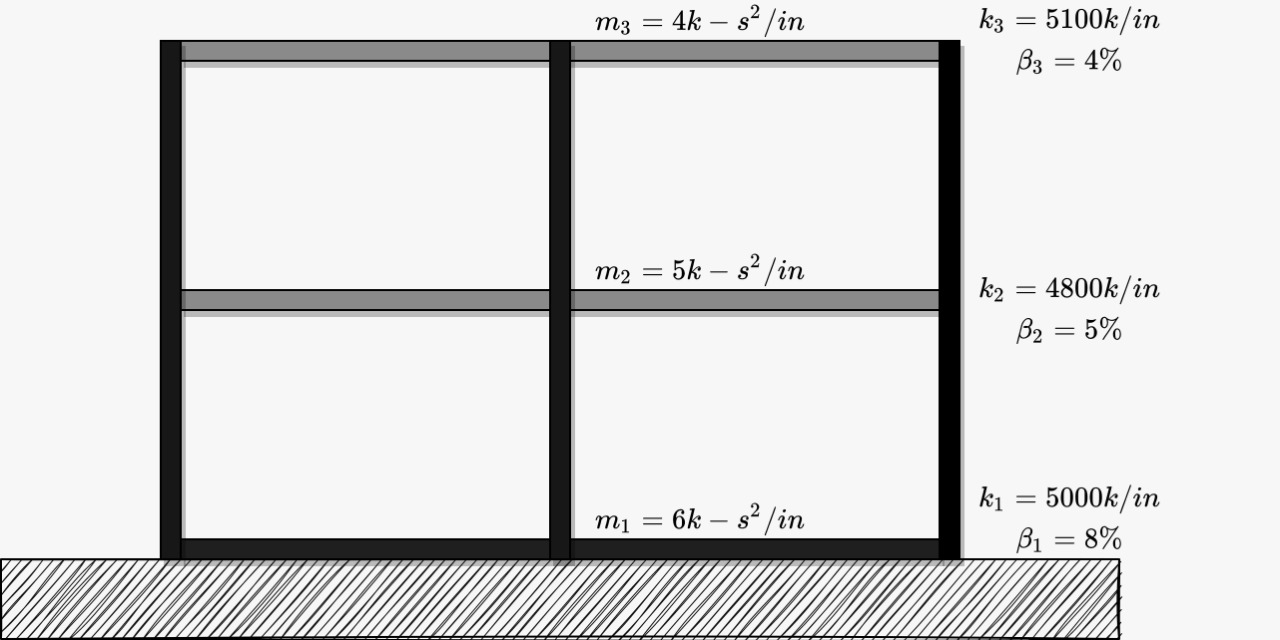

## Modelado Matricial del Problema


$$M\,\ddot{x} \left(t\right)+B\,\dot{x} \left(t\right)+K\,x\left(t\right)=-M\,{\ddot{x} }_g$$


con $\ddot{x_g } \left(t\right)=\alpha \;\sin \left(\omega \;t\right)$

Se construyen las matrices de masa, amortiguamiento y de rigidez:

clear
syms t s alpha omega
assume(omega, "positive")


m = [6 5 4];
b = [0.08 0.05 0.04];
k = [5000 4800 5100];

B =BK(b)

B =     0.1300   -0.0500         0
   -0.0500    0.0900   -0.0400
         0   -0.0400    0.0400


K = BK(k)

K =         9800       -4800           0
       -4800        9900       -5100
           0       -5100        5100


M = MM(m)

M =      6     0     0
     0     5     0
     0     0     4


n = length(M);
x_g_ddot(t) = alpha*sin(omega*t)

$$x\_g\_ddot(t) = \alpha \,\sin\left(\omega \,t\right)$$

## Análisis de Estabilidad y Espacio de Estados

Con estas, se construye el modelo en espacio de estados:


$$\dot{ \textbf{z}} (t) = \textbf{A}\textbf{z}(t) + \textbf{b} \mathbf{\ddot u_g (t)}$$



$$ \textbf{x}(t) = \textbf{C}\textbf{z}(t) + \textbf{D} \mathbf{\ddot u_g (t)}
$$



$$\mathbf{A}=\left\lbrack \begin{array}{cc}
0_{\textrm{NxN}}  & {\mathbf{I}}_{\textrm{NxN}} \\
-{\mathbf{M}}^{-1} \mathbf{K} & -{\mathbf{M}}^{-1} \mathbf{B}
\end{array}\right\rbrack \;\;\mathbf{b}=\;\left\lbrack \begin{array}{c}
0_{\textrm{Nx1}} \\
\mathbf{i}
\end{array}\right\rbrack$$



$$\mathbf{C}=\left\lbrack \begin{array}{cc}
{\mathbf{I}}_{\textrm{NxN}}  & 0_{\textrm{NxN}} 
\end{array}\right\rbrack \;\;\mathbf{D}=\left\lbrack \begin{array}{c}
0_{\textrm{Nx1}} 
\end{array}\right\rbrack$$


A = [zeros(n) eye(n); -inv(M)*K -inv(M)*B]

A = 1.0e+03 *

         0         0         0    0.0010         0         0
         0         0         0         0    0.0010         0
         0         0         0         0         0    0.0010
   -1.6333    0.8000         0   -0.0000    0.0000         0
    0.9600   -1.9800    1.0200    0.0000   -0.0000    0.0000
         0    1.2750   -1.2750         0    0.0000   -0.0000


b = [zeros(n,1); -ones(n, 1)]

b =      0
     0
     0
    -1
    -1
    -1


C = [eye(n) zeros(n)]

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


D = zeros(n,1)

D =      0
     0
     0


Considerando condiciones iniciales cero en el sistema:

z_0 = zeros(2*n,1);

Con las matrices $\mathbf{A \; b \; C \; D}$ se construye el espacio de estados:

sys = ss(A, b, C, D);

Se obtienen los valores propios de la matriz $\mathbf{A}$, que representan los polos en la función de transferencia del sistema completo:

valores_propios = eig(A)

valores_propios =   -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


Debido a que todos los valores propios tienen parte real negativa, por lo que:

- Para toda entrada acotada se produce una salida acotada, es decir, el sistema es BIBO estable.

- El sistema es asintóticamente estable, por lo que el estado estacionario del sistema tiende a cero.

## Análisis del Sistema

Se realizan los diagramas de bode para magnitudes y fase:

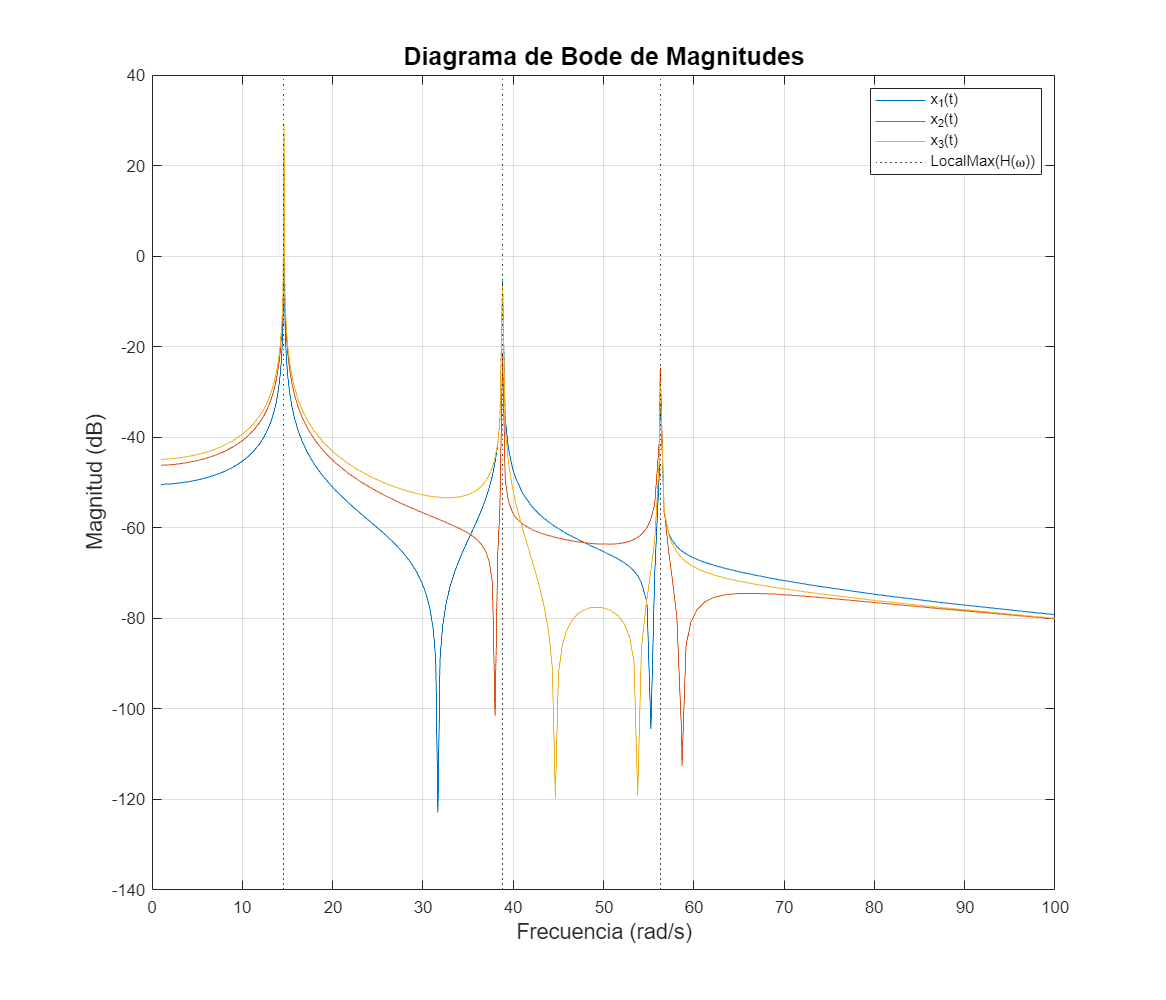

[mag, phase, wout] = bode(sys);

mag = 20*log10(squeeze(mag));
phase = squeeze(phase);

labels = cell(1,n);
for i = 1:n
    labels{1,i} = sprintf("x_%d(t)", i);
end
labels{1, n+1} = "LocalMax(H(\omega))";


figure('Position', [100, 100, 1400, 1200])
plot(wout, mag)
hold on
idx = cell(1,n);
freq_res = [];

for i = 1:n
    [~, loc] = findpeaks(mag(i,:));
    idx{1, i} = loc;
    if i ~= 1
        freq_res = intersect(idx{1,i},idx{1,i-1});
    end
end

pks_sis = zeros(n,length(freq_res));

for i=1:length(freq_res)
    pks_sis(:,i) = mag(:,freq_res(i));
    freq_res(i) = wout(freq_res(i));
end

xline(freq_res, ":k")
hold off
title("Diagrama de Bode de Magnitudes", "FontSize",15)
xlim([0 100])
grid on
xlabel("Frecuencia (rad/s)", "FontSize",13)
ylabel("Magnitud (dB)", "FontSize",13)
legend(labels)

Frecuencias de escalamiento máximo (rad/s):

disp(freq_res)

   14.6176   38.8200   56.2820



Escalamientos máximos (dB):

for i=1:length(freq_res)
    fprintf("Para x_%d(t):\n", i)
    disp(pks_sis(i,:))
end

Para x_1(t):


   22.8651   -5.3123  -30.2976



Para x_2(t):


   27.8470  -21.3429  -24.6415



Para x_3(t):


   29.4402   -6.5425  -28.0729



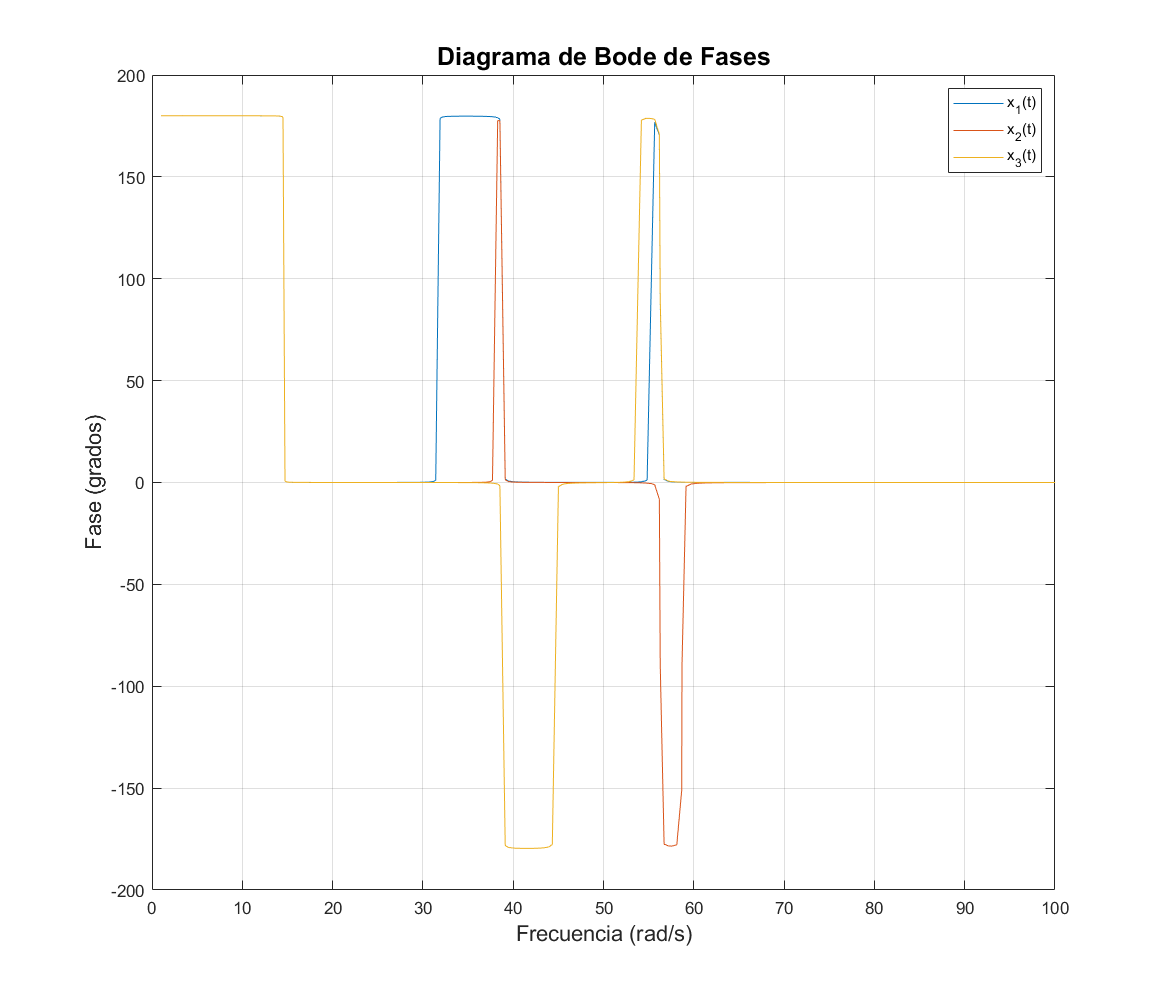

figure('Position', [100, 100, 1400, 1200])
plot(wout, phase)
title("Diagrama de Bode de Fases", "FontSize",15)
xlim([0 100])
xlabel("Frecuencia (rad/s)", "FontSize",13)
ylabel("Fase (grados)", "FontSize",13)
grid on
legend(labels{1,[1 2 3]})

## Solución Analítica del Sistema


$$    \textbf{z}(t) = \mathbf{\Phi}(t) \textbf{z}(0) + \int_{t_0}^t \Phi(t)\mathbf{b\ddot u_g}(\tau) d\tau$$



$$ \textbf{x}(t) = \textbf{C}\textbf{z}(t) + \textbf{D} \mathbf{\ddot u_g (t)}
$$


X(s) = inv(s*eye(n*2)-A)*z_0 + inv(s*eye(n*2)-A)*b*laplace(x_g_ddot);
% la solución es 
z(t) = ilaplace(X);
% Entonces la salida es
x = vpa(C*z(t)+D*x_g_ddot)

## Respuesta en Frecuencia de Resonancia

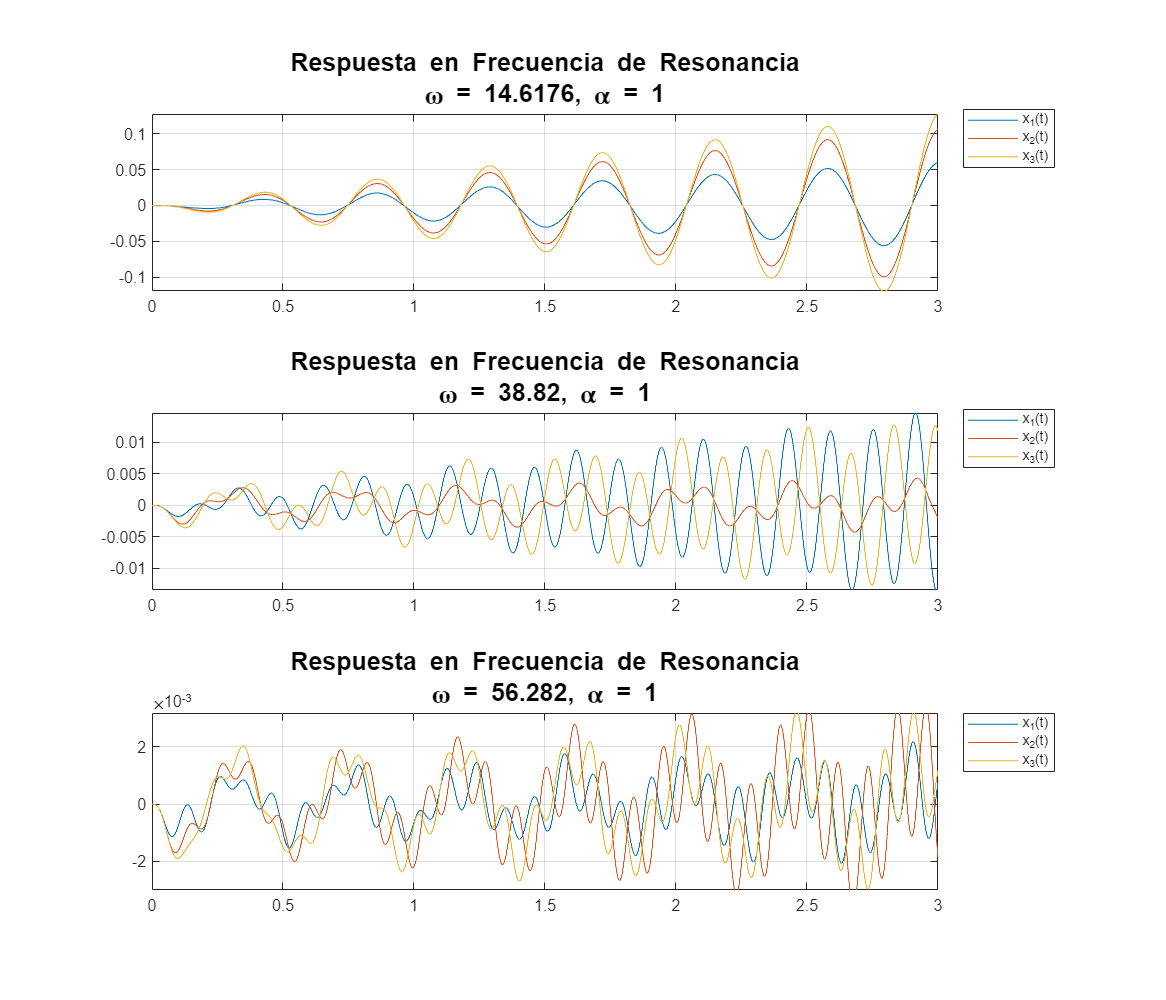

freq_test = [14.6176 38.82 56.282];
a_test = [1 1 1];
t_f = 3; %segs

rows = 3;
cols = 1;
figure('Position', [100, 100, 1400, 1200])
for i = 1:length(freq_test)
    labels = cell(1,n);
    for j = 1:n
        labels{1,j} = sprintf("x_%d(t)", j);
    end

    subplot(rows, cols, i)
    fplot(subs(x(t),[alpha omega],[a_test(i) freq_test(i)]), [0 t_f])
    grid on
    legend(labels, "Location","bestoutside")
    title(["Respuesta en Frecuencia de Resonancia" "\omega = "+freq_test(i)+", \alpha = "+a_test(i)], "FontSize",15)
end

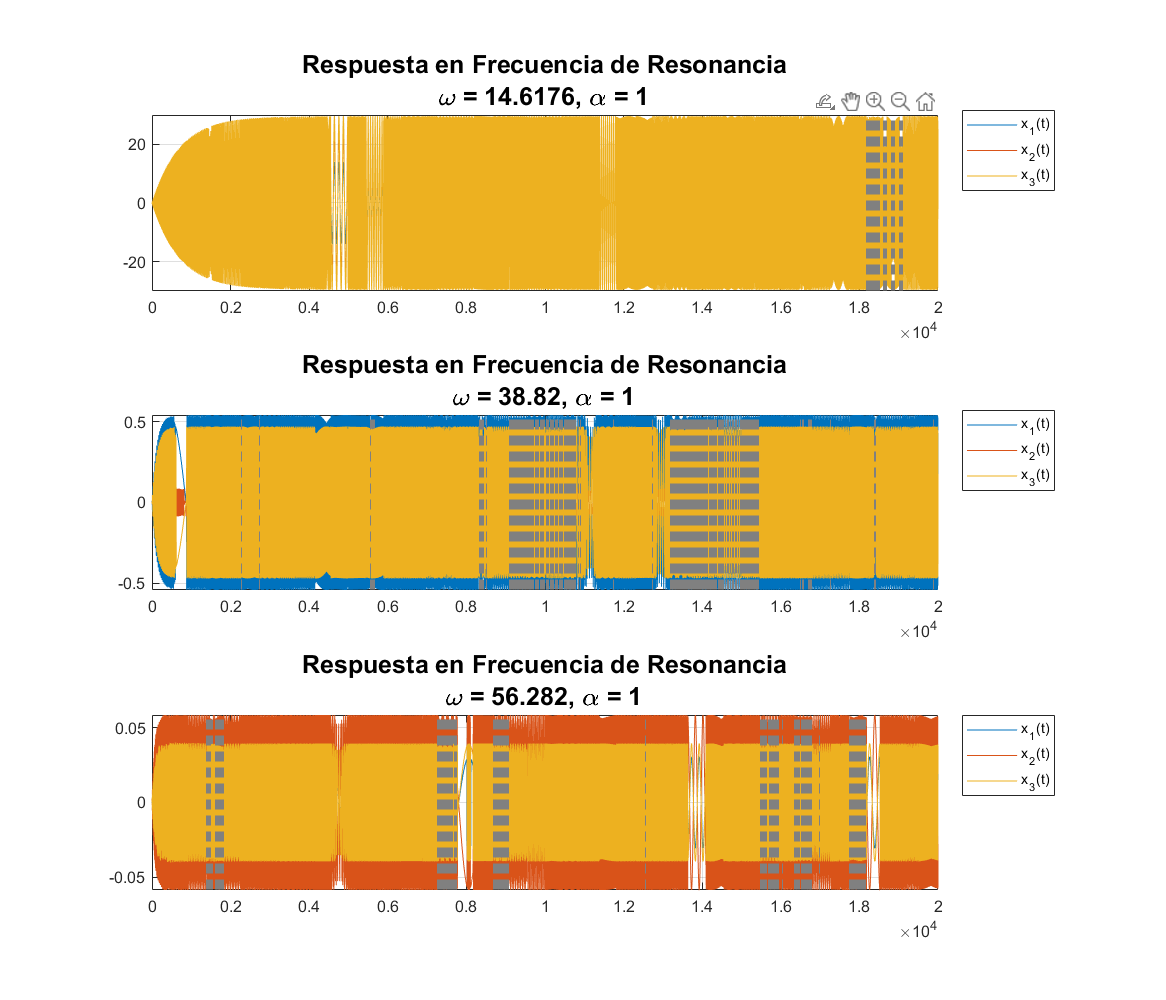

freq_test = [14.6176 38.82 56.282];
a_test = [1 1 1];
t_f = 20000; %segs

rows = 3;
cols = 1;
figure('Position', [100, 100, 1400, 1200])
for i = 1:length(freq_test)
    labels = cell(1,n);
    for j = 1:n
        labels{1,j} = sprintf("x_%d(t)", j);
    end

    subplot(rows, cols, i)
    fplot(subs(x(t),[alpha omega],[a_test(i) freq_test(i)]), [0 t_f])
    grid on
    legend(labels, "Location","bestoutside")
    title(["Respuesta en Frecuencia de Resonancia" "\omega = "+freq_test(i)+", \alpha = "+a_test(i)], "FontSize",15)
end

## Respuesta en Frecuencia

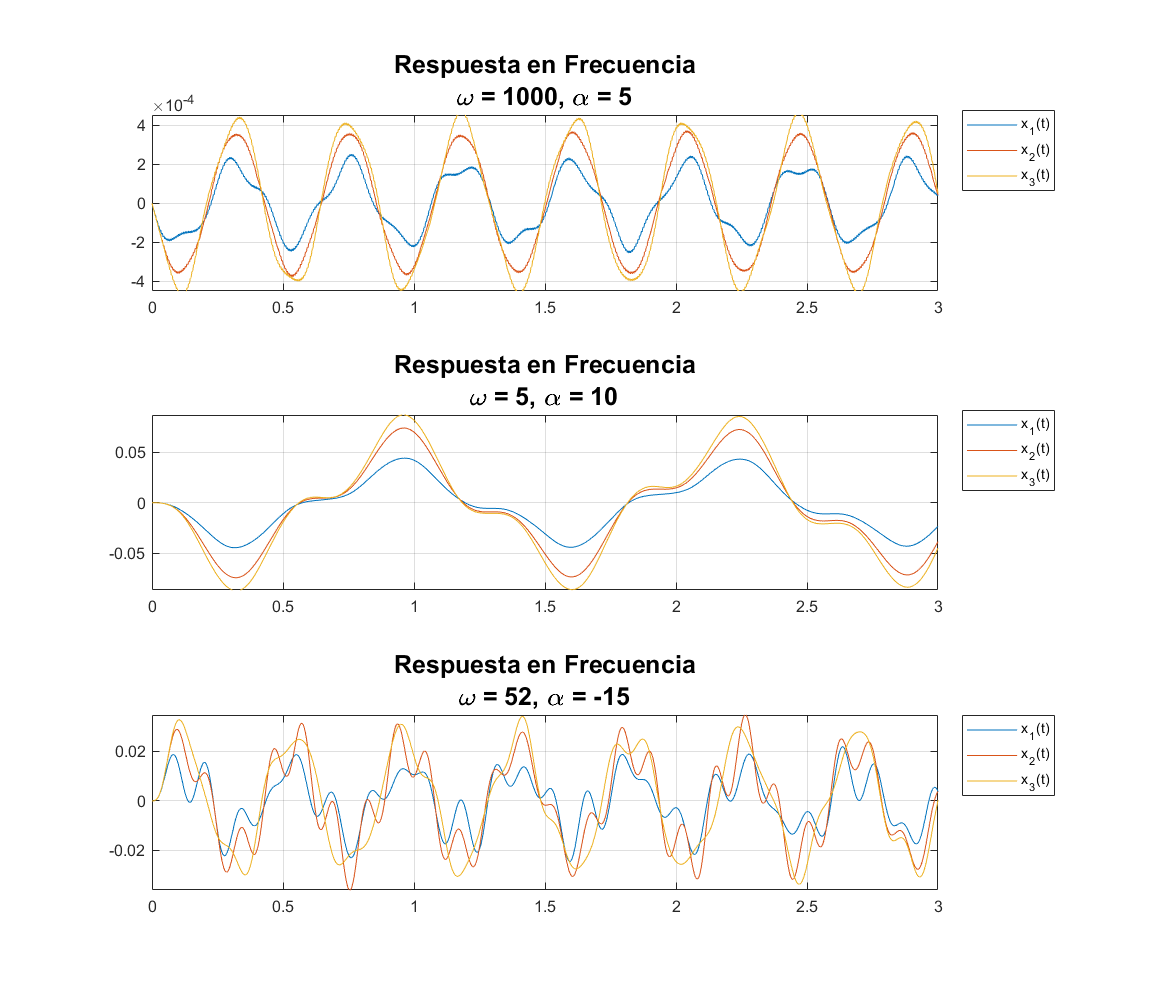

freq_test = [1000, 5,52];
a_test = [5 10 -15];
t_f = 3; %segs

rows = 3;
cols = 1;
figure('Position', [100, 100, 1400, 1200])
for i = 1:length(freq_test)
    labels = cell(1,n);
    for j = 1:n
        labels{1,j} = sprintf("x_%d(t)", j);
    end

    subplot(rows, cols, i)
    fplot(subs(x(t),[alpha omega],[a_test(i) freq_test(i)]), [0 t_f])
    grid on
    legend(labels, "Location","bestoutside")
    title(["Respuesta en Frecuencia" "\omega = "+freq_test(i)+", \alpha = "+a_test(i)], "FontSize",15)
end

## Graficación de Estados en Respuesta a Frecuencia de Resonancia

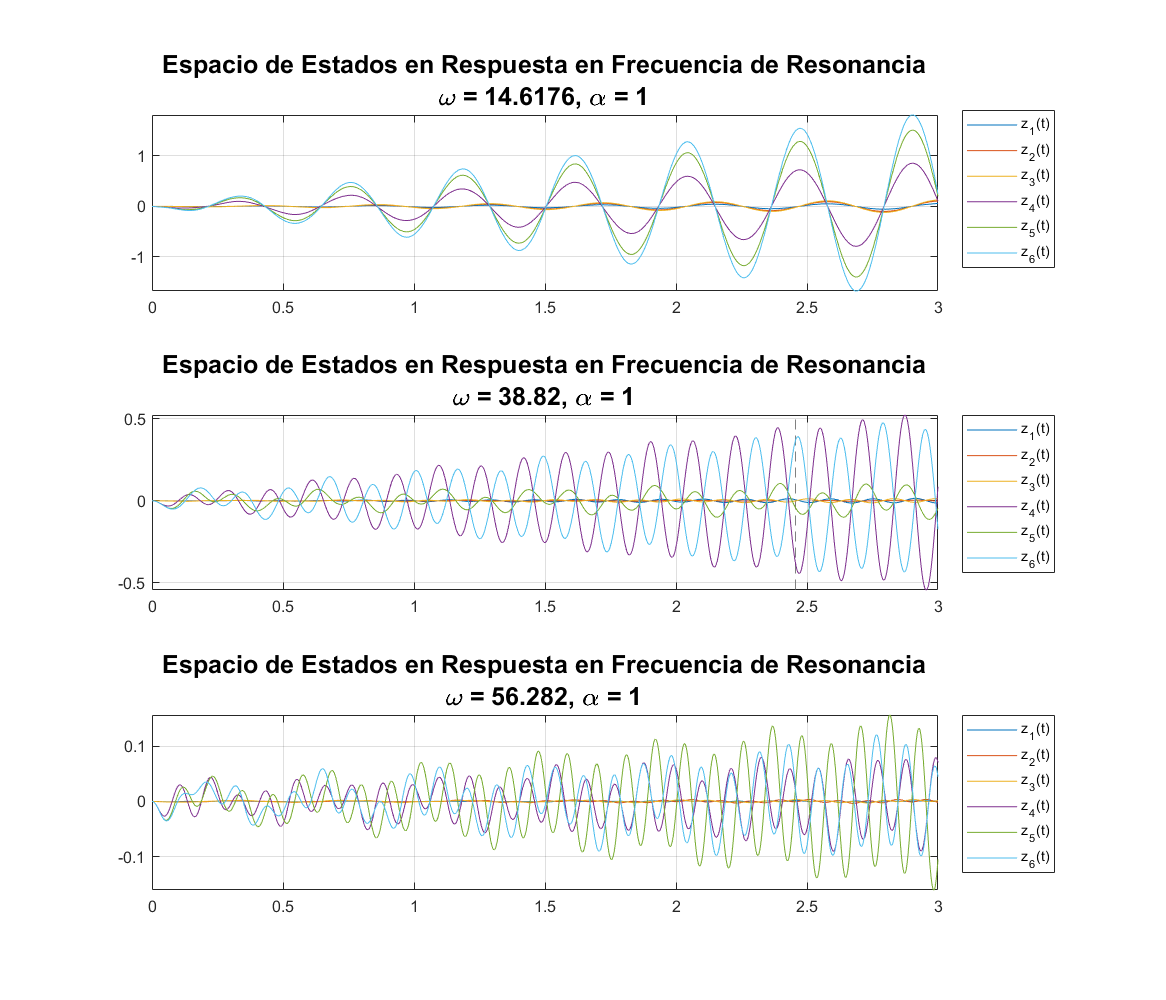

freq_test = [14.6176 38.82 56.282];
a_test = [1 1 1];
t_f = 3; %segs

rows = 3;
cols = 1;
figure('Position', [100, 100, 1400, 1200])
for i = 1:length(freq_test)
    for j = 1:n*2
    labels{1,j} = sprintf("z_%d(t)", j);
    end
    subplot(rows, cols, i)
    fplot(subs(z(t),[alpha omega],[a_test(i) freq_test(i)]), [0 t_f])
    grid on
    legend(labels, "Location", "bestoutside")
    title(["Espacio de Estados en Respuesta en Frecuencia de Resonancia" "\omega = "+freq_test(i)+", \alpha = "+a_test(i)], "FontSize",15)
end

## Graficación de Estados en Respuesta a Frecuencia

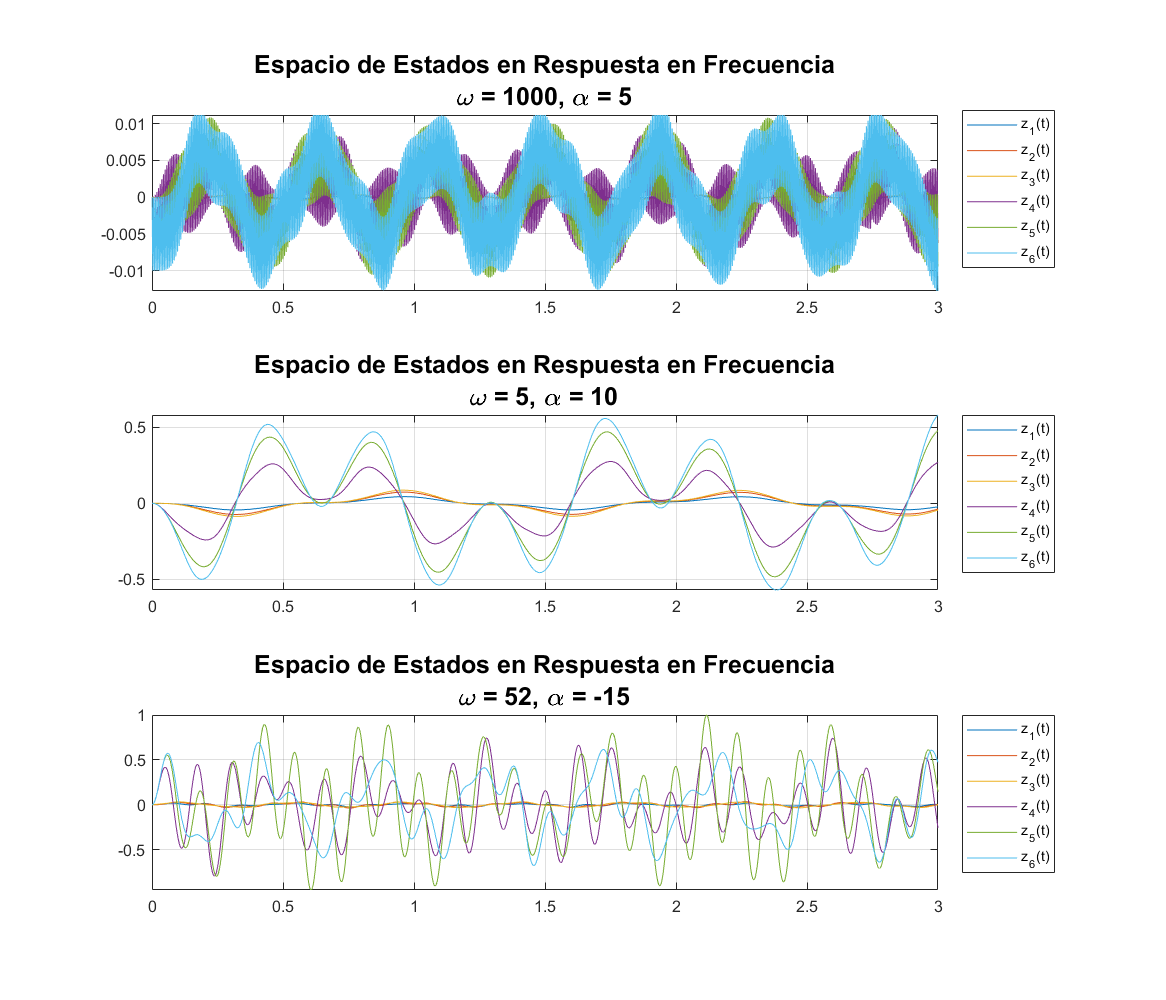

freq_test = [1000, 5,52];
a_test = [5 10 -15];
t_f = 3; %segs

rows = 3;
cols = 1;
figure('Position', [100, 100, 1400, 1200])
for i = 1:length(freq_test)
    for j = 1:n*2
    labels{1,j} = sprintf("z_%d(t)", j);
    end
    subplot(rows, cols, i)
    fplot(subs(z(t),[alpha omega],[a_test(i) freq_test(i)]), [0 t_f])
    grid on
    legend(labels, "Location", "bestoutside")
    title(["Espacio de Estados en Respuesta en Frecuencia" "\omega = "+freq_test(i)+", \alpha = "+a_test(i)], "FontSize",15)
end

function matrix = BK(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    for j = 1:n
        if j == i+1
            matrix(i,j) = -el(i+1);
        elseif j == i-1
            matrix(i,j) = -el(i);
        elseif i==j
            if  i == n && j == n
                matrix(i,j) = el(n);
            else
                matrix(i,j) = el(i)+el(i+1);
            end
        else
            matrix(i,j) = 0;
        end
    end
end
end

function matrix = MM(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    matrix(i,i) = el(i);

end
end